# Clean Messy and Missing Data in Tables

This example shows how to find, clean, and delete table rows with missing data.

## Load Sample Data

Load sample data from a comma-separated text file, `messy.csv`. The file contains many different missing data indicators:

- Empty character vector ('')

- period (.)

- `NA`

- `NaN`

- `-99`

To specify the character vectors to treat as empty values, use the `'TreatAsEmpty'` name-value pair argument with the `readtable` function.

T = readtable('messy.csv','TreatAsEmpty',{'.','NA'})

T = 21×5 table
       A         B          C          D       E 
    ________    ____    __________    ____    ___

    {'afe1'}       3    {'yes'   }       3    4.5
    {'egh3'}     NaN    {'no'    }       7      7
    {'wth4'}       3    {'yes'   }       3      2
    {'atn2'}      23    {'no'    }      23     20
    {'arg1'}       5    {'yes'   }       5      6
    {'jre3'}    34.6    {'yes'   }    34.6     31
    {'wen9'}     234    {'yes'   }     234    240
    {'ple2'}       2    {'no'    }       2      3
    {'dbo8'}       5    {'no'    }       5      2
    {'oii4'}       5    {'yes'   }       5      6
    {'wnk3'}     245    {'yes'   }     245    270
    {'abk6'}     563    {0×0 char}     563    561
    {'pnj5'}     463    {'no'    }     463    462
    {'wnn3'}       6    {'no'    }       6      5
    {'oks9'}  

`T` is a table with 21 rows and five variables. `'TreatAsEmpty'` only applies to numeric columns in the file and cannot handle numeric literals, such as `'-99'`.

## Summarize Table

View the data type, description, units, and other descriptive statistics for each variable by creating a table summary using the `summary` function.

summary(T)

Variables:

    A: 21×1 cell array of character vectors

    B: 21×1 double

        Values:

            Min             -99   
            Median          14    
            Max             563   
            NumMissing      3     

    C: 21×1 cell array of character vectors

    D: 21×1 double

        Values:

            Min             -99   
            Median          7     
            Max             563   
            NumMissing      2     

    E: 21×1 double

        Values:

            Min         -99   
            Median       14   
            Max         561   



When you import data from a file, the default is for `readtable` to read any variables with nonnumeric elements as a cell array of character vectors.

## Find Rows with Missing Values

Display the subset of rows from the table, `T`, that have at least one missing value.

TF = ismissing(T,{'' '.' 'NA' NaN -99});
T(any(TF,2),:)

ans = 5×5 table
       A         B         C          D      E 
    ________    ___    __________    ___    ___

    {'egh3'}    NaN    {'no'    }      7      7
    {'abk6'}    563    {0×0 char}    563    561
    {'wba3'}    NaN    {'yes'   }    NaN     14
    {'poj2'}    -99    {'yes'   }    -99    -99
    {'gry5'}    NaN    {'yes'   }    NaN     21


`readtable` replaced `'.'` and `'NA'` with `NaN` in the numeric variables,  `B`, `D`, and `E`.

## Replace Missing Value Indicators

Clean the data so that the missing values indicated by code `-99` have the standard MATLAB® numeric missing value indicator, `NaN`.

T = standardizeMissing(T,-99)

T = 21×5 table
       A         B          C          D       E 
    ________    ____    __________    ____    ___

    {'afe1'}       3    {'yes'   }       3    4.5
    {'egh3'}     NaN    {'no'    }       7      7
    {'wth4'}       3    {'yes'   }       3      2
    {'atn2'}      23    {'no'    }      23     20
    {'arg1'}       5    {'yes'   }       5      6
    {'jre3'}    34.6    {'yes'   }    34.6     31
    {'wen9'}     234    {'yes'   }     234    240
    {'ple2'}       2    {'no'    }       2      3
    {'dbo8'}       5    {'no'    }       5      2
    {'oii4'}       5    {'yes'   }       5      6
    {'wnk3'}     245    {'yes'   }     245    270
    {'abk6'}     563    {0×0 char}     563    561
    {'pnj5'}     463    {'no'    }     463    462
    {'wnn3'}       6    {'no'    }       6      5
    {'oks9'}  

`standardizeMissing` replaces three instances of `-99` with `NaN`.

Create a new table, `T2`, and replace missing values with values from previous rows of the table. `fillmissing` provides a number of ways to fill in missing values.

T2 = fillmissing(T,'nearest')

T2 = 21×5 table
       A         B         C        D       E 
    ________    ____    _______    ____    ___

    {'afe1'}       3    {'yes'}       3    4.5
    {'egh3'}       3    {'no' }       7      7
    {'wth4'}       3    {'yes'}       3      2
    {'atn2'}      23    {'no' }      23     20
    {'arg1'}       5    {'yes'}       5      6
    {'jre3'}    34.6    {'yes'}    34.6     31
    {'wen9'}     234    {'yes'}     234    240
    {'ple2'}       2    {'no' }       2      3
    {'dbo8'}       5    {'no' }       5      2
    {'oii4'}       5    {'yes'}       5      6
    {'wnk3'}     245    {'yes'}     245    270
    {'abk6'}     563    {'no' }     563    561
    {'pnj5'}     463    {'no' }     463    462
    {'wnn3'}       6    {'no' }       6      5
    {'oks9'}      23    {'yes'}      23     25
    {'wba3'}  

T2a = knnimpute(table2array(T(:,{'B','D','E'})),1);

T2a = [table(T2a(:,1),T2a(:,2), T2a(:,3)), T(:,{'A','C'})];
T2a.Properties.VariableNames = {'B','D','E','A','C'}

T2a = 21×5 table
     B       D       E        A            C     
    ____    ____    ___    ________    __________

       3       3    4.5    {'afe1'}    {'yes'   }
       7       7      7    {'egh3'}    {'no'    }
       3       3      2    {'wth4'}    {'yes'   }
      23      23     20    {'atn2'}    {'no'    }
       5       5      6    {'arg1'}    {'yes'   }
    34.6    34.6     31    {'jre3'}    {'yes'   }
     234     234    240    {'wen9'}    {'yes'   }
       2       2      3    {'ple2'}    {'no'    }
       5       5      2    {'dbo8'}    {'no'    }
       5       5      6    {'oii4'}    {'yes'   }
     245     245    270    {'wnk3'}    {'yes'   }
     563     563    561    {'abk6'}    {0×0 char}
     463     463    462    {'pnj5'}    {'no'    }
       6       6      5    {'wnn3'}    {'no'    }
      23    

## Remove Rows with Missing Values

Create a new table, `T3`, that contains only the rows from `T` without missing values.

T3 = rmmissing(T)

T3 = 16×5 table
       A         B         C        D       E 
    ________    ____    _______    ____    ___

    {'afe1'}       3    {'yes'}       3    4.5
    {'wth4'}       3    {'yes'}       3      2
    {'atn2'}      23    {'no' }      23     20
    {'arg1'}       5    {'yes'}       5      6
    {'jre3'}    34.6    {'yes'}    34.6     31
    {'wen9'}     234    {'yes'}     234    240
    {'ple2'}       2    {'no' }       2      3
    {'dbo8'}       5    {'no' }       5      2
    {'oii4'}       5    {'yes'}       5      6
    {'wnk3'}     245    {'yes'}     245    270
    {'pnj5'}     463    {'no' }     463    462
    {'wnn3'}       6    {'no' }       6      5
    {'oks9'}      23    {'yes'}      23     25
    {'pkn4'}       2    {'no' }       2      5
    {'adw3'}      22    {'no' }      22     26
    {'bas8'}  

`T3` contains 16 rows and five variables.

## Organize Data

Sort the rows of `T3` in descending order by `C`, and then sort in ascending order by `A`.

T3 = sortrows(T2,{'C','A'},{'descend','ascend'})

T3 = 21×5 table
       A         B         C        D       E 
    ________    ____    _______    ____    ___

    {'abk6'}     563    {'yes'}     563    561
    {'afe1'}       3    {'yes'}       3    4.5
    {'arg1'}       5    {'yes'}       5      6
    {'gry5'}      23    {'yes'}      23     21
    {'jre3'}    34.6    {'yes'}    34.6     31
    {'oii4'}       5    {'yes'}       5      6
    {'oks9'}      23    {'yes'}      23     25
    {'poj2'}      22    {'yes'}      22     26
    {'wba3'}      23    {'yes'}      23     14
    {'wen9'}     234    {'yes'}     234    240
    {'wnk3'}     245    {'yes'}     245    270
    {'wth4'}       3    {'yes'}       3      2
    {'adw3'}      22    {'no' }      22     26
    {'atn2'}      23    {'no' }      23     20
    {'bas8'}      23    {'no' }      23     20
    {'dbo8'}  

In `C`, the rows are grouped first by `'yes'`, followed by `'no'`. Then in `A`, the rows are listed alphabetically.

Reorder the table so that `A` and `C` are next to each other.

T3 = T3(:,{'A','C','B','D','E'})

T3 = 21×5 table
       A           C        B       D       E 
    ________    _______    ____    ____    ___

    {'abk6'}    {'yes'}     563     563    561
    {'afe1'}    {'yes'}       3       3    4.5
    {'arg1'}    {'yes'}       5       5      6
    {'gry5'}    {'yes'}      23      23     21
    {'jre3'}    {'yes'}    34.6    34.6     31
    {'oii4'}    {'yes'}       5       5      6
    {'oks9'}    {'yes'}      23      23     25
    {'poj2'}    {'yes'}      22      22     26
    {'wba3'}    {'yes'}      23      23     14
    {'wen9'}    {'yes'}     234     234    240
    {'wnk3'}    {'yes'}     245     245    270
    {'wth4'}    {'yes'}       3       3      2
    {'adw3'}    {'no' }      22      22     26
    {'atn2'}    {'no' }      23      23     20
    {'bas8'}    {'no' }      23      23     20
    {'dbo8'}  

*Copyright 2012 The MathWorks, Inc.*

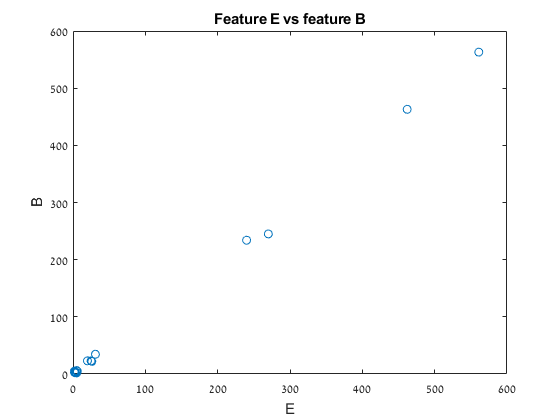

x_train=table2array(T(~(TF(:,5)+TF(:,2)),'E'));
y_train=table2array(T(~(TF(:,5)+TF(:,2)),'B'));
figure; plot(x_train,y_train,'o'); title('Feature E vs feature B'); xlabel('E'); ylabel('B')

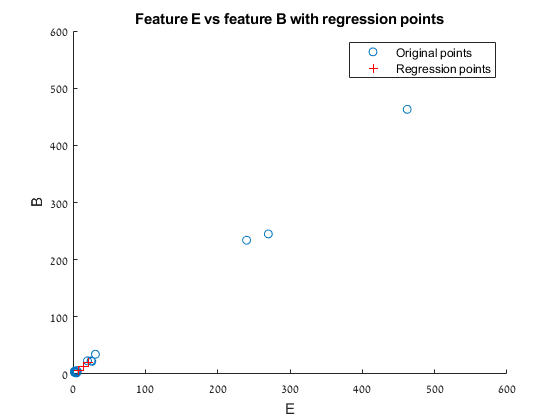


x_pred=table2array(T((TF(:,5)-TF(:,2))~=0,'E'));
b=regress(y_train,[ones(size(x_train)) x_train]); % Compute the coefficients accordind to the feature E
y_pred=[ones(size(x_pred)) x_pred]*b; 

figure; hold on
plot(x_train,y_train,'o')
plot(x_pred,y_pred,'+r')
title('Feature E vs feature B with regression points'); xlabel('E'); ylabel('B')
legend('Original points', 'Regression points')